# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** :  강지수**

**학번**** : 201910912**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : **

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

x=[1 2 2 1]; N=4 ; X=dft(x,N);
mag = abs(X), phaX = angle(X)*180/pi

mag =     6.0000    1.4142    0.0000    1.4142


phaX =          0 -135.0000  -90.0000  135.0000



n1= 0:3; x1= [1 2 2 1]; N1 = length(n1); N=50;
[X1]=dft([x1,zeros(1,N-N1)],N); w= (0:N/2)*2*pi/N;
magX1= abs(X1(1:N/2+1)), phaX1= angle(X1(1:N/2+1))*180/pi 

magX1 =     6.0000    5.9567    5.8280    5.6178    5.3323    4.9798    4.5707    4.1167    3.6308    3.1266    2.6180    2.1185    1.6410    1.1972    0.7971    0.4490    0.1591    0.0690    0.2340    0.3372    0.3820    0.3743    0.3221    0.2349    0.1236    0.0000


phaX1 =          0  -10.8000  -21.6000  -32.4000  -43.2000  -54.0000  -64.8000  -75.6000  -86.4000  -97.2000 -108.0000 -118.8000 -129.6000 -140.4000 -151.2000 -162.0000 -172.8000   -3.6000  -14.4000  -25.2000  -36.0000  -46.8000  -57.6000  -68.4000  -79.2000  178.5679


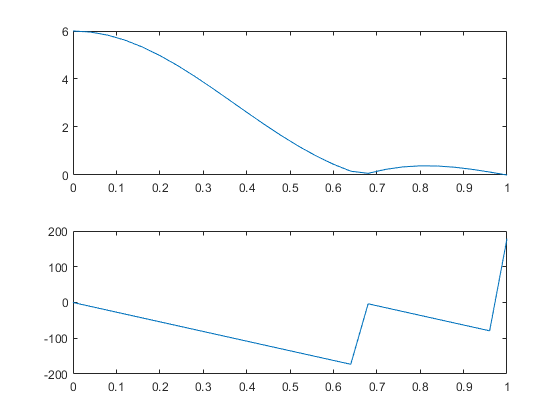


subplot(2,1,1); plot(w/pi,magX1); 
subplot(2,1,2); plot(w/pi, phaX1);

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.


x=[1,2,2,1,zeros(1,12)]; N=16 ; X= dft(x,N);
mag = abs(X), phaX = angle(X)*180/pi

mag =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


phaX =          0  -33.7500  -67.5000 -101.2500 -135.0000 -168.7500  -22.5000  -56.2500   90.0000   56.2500   22.5000  168.7500  135.0000  101.2500   67.5000   33.7500


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

xn = [4 1 -1 1]; N=4; Xk = dfs(xn,N)

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$


xn = [4 1 -1 1]; N=4; Xk = dfs(xn,N)

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

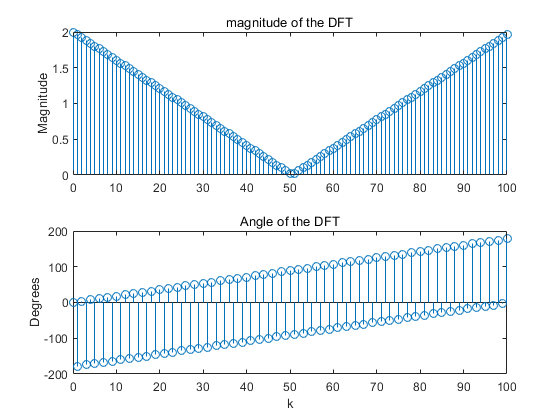

n = 0:100; xn = sinc((n-50)/2) .^2; 
N = length(xn); Xk = dft(xn,N); k = 0:N-1;
mag1 = abs(Xk); pha1 = angle(Xk)*180/pi ;
subplot(2,1,1) ; H1 = stem(k,mag1); title ('magnitude of the DFT'); ylabel('Magnitude');
subplot(2,1,2); H2 = stem(k,pha1); title ('Angle of the DFT') ; xlabel('k');  ylabel('Degrees');

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

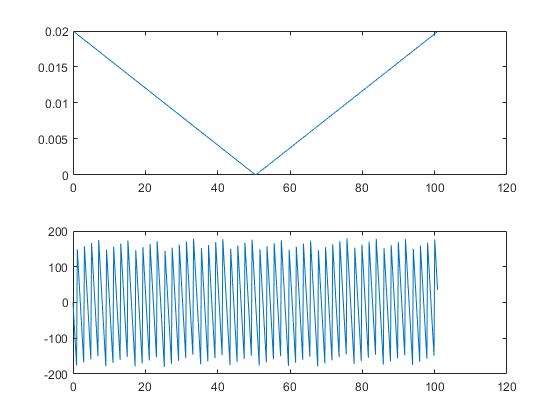

xn = sinc((n-50)/2) .^2; N = length(xn);
[X,w]=freqz(xn,100,'whole'); 
mag2=abs(X); pha2=angle(X)*180/pi;
W= (2*pi)/N; 
subplot(2,1,1); plot(w/W,mag2);
subplot(2,1,2); plot(w/W,pha2);

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

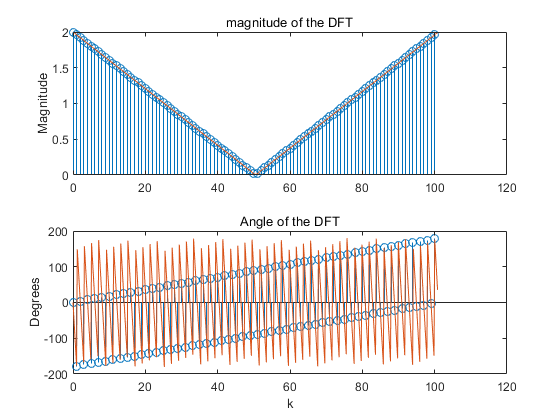

n = 0:100; xn = sinc((n-50)/2) .^2; 
N = length(xn); Xk = dft(xn,N); k = 0:N-1;
mag1 = abs(Xk); pha1 = angle(Xk)*180/pi ;
subplot(2,1,1) ; H1 = stem(k,mag1); title ('magnitude of the DFT'); ylabel('Magnitude'); hold on
subplot(2,1,2); H2 = stem(k,pha1); title ('Angle of the DFT') ; xlabel('k');  ylabel('Degrees'); hold on
xn = sinc((n-50)/2) .^2; N = length(xn);
[X,w]=freqz(xn,1,'whole'); 
mag2=abs(X); pha2=angle(X)*180/pi;
W= (2*pi)/N;
subplot(2,1,1); plot(w/W,mag2); 
subplot(2,1,2); plot(w/W,pha2);

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

- 재구성을 할 수 있다. 보간공식은 $X\left(e^{j\omega } \right)$ = $\sum_0^{N-1} X\left(k\right)\phi \left(w-\frac{2\pi k}{N}\right)$을 이용하여 재구성하면 된다.

function [Xk] = dft(xn,N)
n= [0:1:N-1];
k= [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk= WN .^ nk ;
Xk = xn * WNnk;
 
end

function [xn] = idft(Xk,N)
n= [0:1:N-1];
k= [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end

function [Xk] = dfs(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [xn] = idfs(Xk,N)
n= [0:1:N-1];
k= [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end
